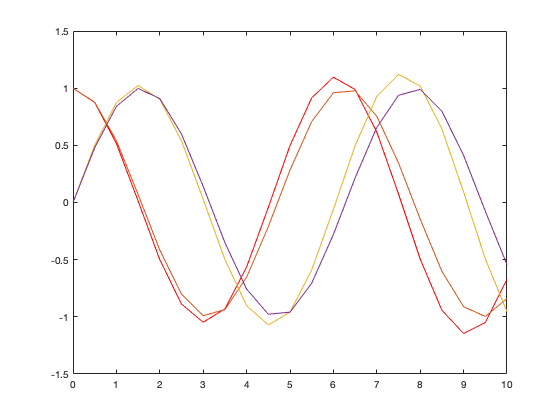

[X Y] = EMsolves(0,-1,1,0,1,0,10,20);
t = linspace(0,10,21);
plot (t,X, 'r')
hold on 
plot(t,cos(t))
plot(t,Y)

plot(t,sin(t))

hold off

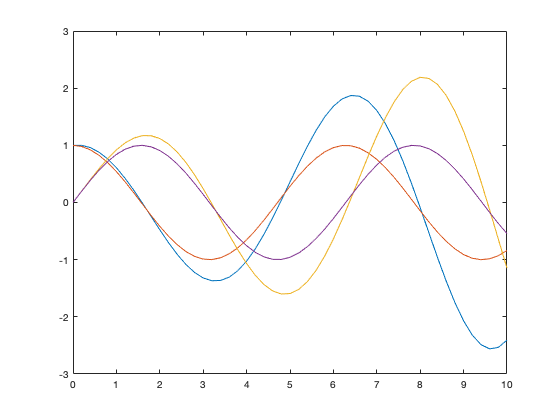


[X, Y] = EMsolve(0,-1,1,0,1,0,10,50);
t = linspace(0,10,51);
plot (t,X)
hold on 
plot(t,cos(t))
plot(t,Y)

plot(t,sin(t))

function [x,y] = EMsolve(e,f,g,h,x_0,y_0,T,N)
    A = [e f; g h];
    dt = T/N;
    t = 0:dt:T;
    SOL = NaN(2,length(t));
    SOL(1,1) = x_0;
    SOL(2,1) = y_0;
    for k = 2:length(t)
        SOL(:,k) = SOL(:,k-1) + dt*A*SOL(:,k-1);
    end
    x = SOL(1,:);
    y = SOL(2,:);
end



function [x,y] = EMsolves(e,f,g,h,x_0,y_0,T,N)
    A = [e f; g h];
    dt = T/N;
    t = 0:dt:T;
    SOL = NaN(2,length(t));
    SOL(1,1) = x_0;
    SOL(2,1) = y_0;
    for k = 2:length(t)
        SOL(:,k) = SOL(:,k-1) + dt*A*SOL(:,k-1);
        SOL(:,k) = SOL(:,k-1) + (dt/2)*(A*SOL(:,k-1) + A*SOL(:,k));
    end
    x = SOL(1,:);
    y = SOL(2,:);
end


